close all;
clear all;
% define inputs and prepare for CBC
w0 = 2*pi;
target = 1.5;
x_init = [0, 0];
periods = 100;
dt = 1/1000;
[model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);

% control parameters
% control law
control.k1 = 1;
control.k2 = 0.1;

control.psi = 0;
control.psi_dot = 0;
psi_lim = 20;

% tip_error = x(end, 1) - ref_x(end, 1)*k1; %gain shaping
% psi_dot = k2*tip_error.^2;
% psi = psi + psi_dot;
% psi_history = zeros(length(trial.t_span), 1);
% volt_history = zeros(length(trial.t_span), 1);
% tip_history = zeros(length(trial.t_span), 1);



% define reference
w0 = input.w0;
A_target = control.target_vec(:, 1);
B_target = control.target_vec(:, 2);
k_num = control.k_num;
wk = w0*(1:k_num)';
ref_x = @(t) sum(A_target.*cos(wk.*t) + B_target.*sin(wk.*t));

% simulate itteration:
for k = 1:length(trial.t_span)-1
    tk = trial.t_span(k);
    tkp1 = trial.t_span(k+1);
    tspan = [tk, tkp1];
    
    % Simulation loop --------------------------------------------------------
    p_external = @(t) input.force;
    % p_external = @(t) 10*sin(input.w0*t);
    % Define ODE function
    odefun = @(t, X) [X(2); 
                      (1 / model.m) * (p_external(t) - model.c * X(2) - model.k * X(1) - model.alpha * X(1)^3)];
    
    % Simulate between time steps
    [trial.t, trial.X] = ode45(odefun, [tk, tkp1], trial.x_init);
    trial.x_init = trial.X(end, :);
    trial.tip_history(k+1) = trial.X(end, 1);

    tip_error = trial.X(end, 1) - ref_x(trial.t(end))*control.k1;
    control.psi_dot = control.k2 * tip_error.^2;
    
    % update psi
    if control.psi >= psi_lim
        control.psi = psi_lim;
    else
        control.psi = control.psi + control.psi_dot * trial.dt;  % Euler integration
    end

    trial.psi_history(k+1, 1) = control.psi;
    input.force = control.psi * tip_error;
    trial.force_history(k+1) = input.force;
    if input.force > 1e9
        "control_volt too high: " + control_volt
        break
    end
end

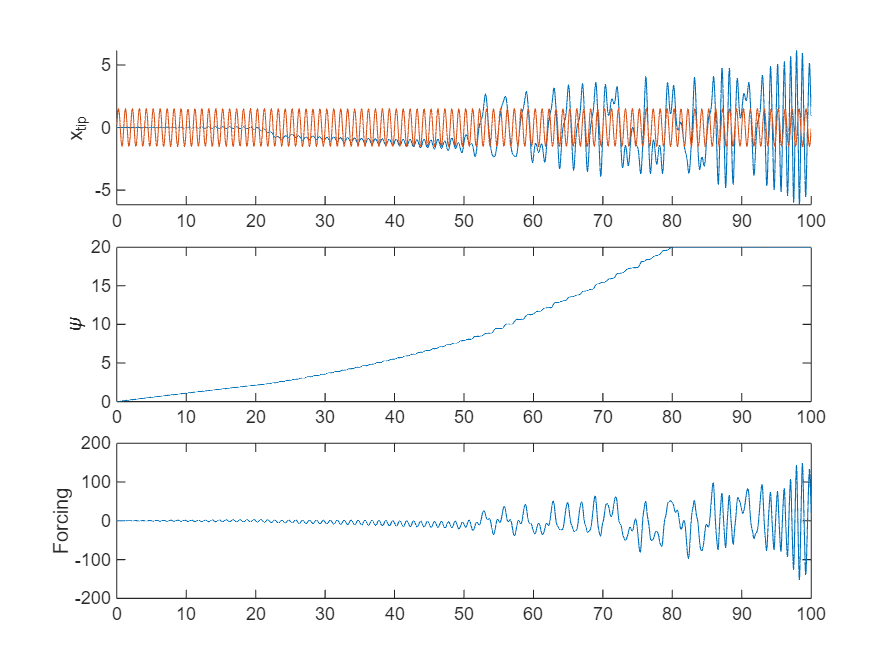

tiledlayout(3,1, "TileSpacing","compact")
nexttile;
hold on;
plot(trial.t_span, trial.tip_history)
plot(trial.t_span, arrayfun(ref_x, trial.t_span))
ylabel("x_{tip}")

nexttile;
plot(trial.t_span, trial.psi_history)
ylabel("\psi");
nexttile;
plot(trial.t_span, trial.force_history)
ylabel("Forcing");

% % extract amplitude
[t_lin, x_lin] = f_get_last_n_periods(trial.t_span, trial.force_history, 5);
[A_vec,B_vec] = f_get_fft_components(t_lin, x_lin, input.w0, control.k_num)

A_vec =    39.8964
   -1.9404
   -2.7721
   -0.0068
   -0.0371
   -0.2382
   -0.1013


B_vec =   -87.4319
    0.9138
    2.7199
   -0.9050
   -0.1181
    0.0763
    0.0051


[t_lin2, x_reconstructed] = f_get_reconstructed_wave(A_vec, B_vec, t_lin, input.w0)

t_lin2 =    94.3620   94.3630   94.3640   94.3650   94.3660   94.3670   94.3680   94.3690   94.3700   94.3710   94.3720   94.3730   94.3740   94.3750   94.3760   94.3770   94.3780   94.3790   94.3800   94.3810   94.3820   94.3830   94.3840   94.3850   94.3860   94.3870   94.3880   94.3890   94.3900   94.3910   94.3920   94.3930   94.3940   94.3950   94.3960   94.3970   94.3980   94.3990   94.4000   94.4010   94.4020   94.4030   94.4040   94.4050   94.4060   94.4070   94.4080   94.4090   94.4100   94.4110


x_reconstructed =   -94.2737  -94.0339  -93.7899  -93.5418  -93.2896  -93.0334  -92.7732  -92.5091  -92.2411  -91.9693  -91.6938  -91.4145  -91.1316  -90.8451  -90.5550  -90.2615  -89.9645  -89.6642  -89.3605  -89.0535  -88.7434  -88.4300  -88.1136  -87.7941  -87.4715  -87.1461  -86.8177  -86.4865  -86.1524  -85.8156  -85.4761  -85.1340  -84.7893  -84.4420  -84.0921  -83.7399  -83.3852  -83.0281  -82.6687  -82.3071  -81.9432  -81.5771  -81.2089  -80.8385  -80.4661  -80.0916  -79.7152  -79.3368  -78.9565  -78.5743


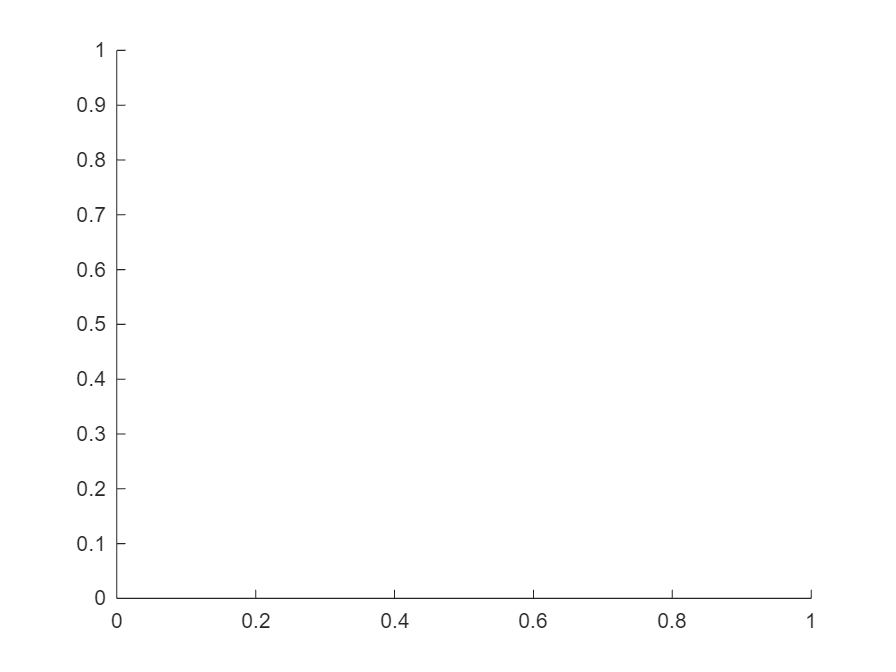


figure;
hold on;

plot(trial.t_span, volt_history);

Unrecognized function or variable 'volt_history'.

plot(t_lin2, x_reconstructed);
% amplitude = sqrt(sum(A_vec.^2 + B_vec.^2));
% % % adjust gain shaping
% amp_err = target_amp/amplitude
% if abs(amp_err-1) < 0.01
%     "within tolerance > model.k1 = " + model.k1
% else
%     model.k1 = model.k1 + 0.1*model.k1 * (amp_err-1);
% end

% control.Kd = 5;
% control.Kp = 90;
% % control.target_vec = ty2
% [input_out, trial_out] = closedloop_test(model, input, trial, control);

% [f] = plot_CL_inner(input_out, trial_out, control);